# Case 5

Coulomb non-linear fit

clear; 
clc;

## Load data 

url = "https://raw.githubusercontent.com/cararm4073/tec-archive/main/university/EF26/F1008/Lab2/Lab2_Case2.csv";
data = readtable(url,"VariableNamingRule","preserve");

r = data{:,1}; % distance
F = data{:,2}; % force

## Model definition

F = A / r²

model = @(A,x) A ./ (x.^2);

Parameters

A0 = 1e-4; %0.0001
A_fit = lsqcurvefit(model,A0,r,F); %use non-linear min squares, using the model defined previously, the initial value, r for the x-axys and f for the f-axys


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


Predicted values

fit = model(A_fit,r);

Residuals

residuals = F - fit;

R²

SS_res = sum((F - fit).^2);
SS_tot = sum((F - mean(F)).^2);
R2 = 1 - SS_res/SS_tot;

## Plotting

Smooth line

r_smooth = linspace(min(r),max(r),500);
F_smooth = model(A_fit,r_smooth);

Plot

figure;
scatter(r, F , 50, F, 'filled')
colormap('turbo')
hold on

plot(r_smooth,F_smooth,'r', 'LineWidth',1.5);

Error line

plot([r r]',[F fit]','k--');

Plot settings

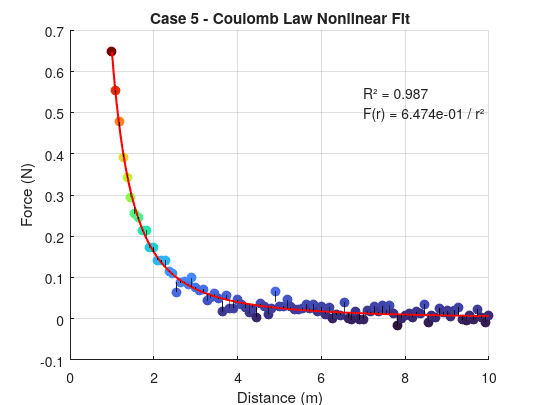

xlabel('Distance (m)');
ylabel('Force (N)');
title('Case 5 - Coulomb Law Nonlinear Fit');
grid on;

text1 = sprintf('F(r) = %.3e / r²',A_fit);
text2 = sprintf('R² = %.3f',R2);
text(7,0.5,text1);
text(7,0.55,text2);

hold off